# **2. Line searches & functions of one variable**

- When it comes to minimising a function of several variables, we tend to use repeated minimisation of a function along search directions. In other words, minimising a multi-variable function involves repeated minimisation of the function for a single variable. We will look at this is more detail in due course.

- Nevertheless, the fact remains that the procedure of finding the minimum of functions of one variable is an important element in any optimisation method.

- We are now going to deal with such procedures in this section of the notes. In particular we are going to concentrate on two types of search methods – one based on fixed interval reductions (Grid, Fibonacci and Golden Section), the other based on curve fitting (Quadratic).

- Note that  these search methods are iterative approaches which continue until the minimum is found to be within the required degree of accuracy. ***As such, these methods***  ***are better suited for computer simulation!***

- This approach is useful in cases where:

- a mathematical expression for $F(x)$ is unknown

- calculating the solution of $\nabla$$F(x) = 0$ proves exceedingly difficult!

- In the case of (1) above, an example might be an industrial process that we do not have a mathematical expression for. However, we can still measure the output for given inputs by physically conducting the actual process itself.

- This example highlights one of the key features of a good optimisation algorithm. Running the industrial process is timely and expensive and therefore each time we want to see the effect of an input on the industrial process means extra cost for the company involved. 

- Clearly, therefore, ***a good optimisation is one that can converge on the minimum in the least possible number of function evaluations.***

- Finally, note that all these search methods assume that we can locate a range $[a\quad b]$ in which a single local minimum exists. In practice, how do we find such an interval?

### **Finding interval containing minimum**

- The first step is to calculate $F(x)$ at some point $x = k$. 

- We then need to find a point $b = k + h$, where h is a positive step. 

- If $F(k+h) > F(k)$, then we are moving away from the minimum and therefore, we now need to move in the opposite direction from $k$, i.e. we need to consider $F(k-h)$.

- If $F(k-h) > F(k)$, then we have found a bracketing interval $[k-h, k+h]$. 

- If not then we move further in the same direction, subtracting $2h$ each time we fail to establish an end for the bracketing interval, i.e. we consider $F(k-3h), F(k-7h)$, etc.

- If $F(k+h) < F(k),$ however, then we continue moving in the same direction and consider $F(k+3h), F(k+7h)$, etc… until we find a function value greater than $F(k+h)$.

- So, let us say that we find $F(k+3h) > F(k+h)$, then the bracketing interval is $[k,k+3h]$.

### 2.1 **The Grid method**

- This is the simplest method of determining the minimum of $F(x)$.

- We split the range $[a \quad b]$ into a number of subintervals of equal size. We then identify the subinterval which contains the minimum and repeat the process of subdividing.

- This process continues until we obtain a subinterval of suitable accuracy

#### Illustrative Example

- Consider the following function: $f(x) = x^3 – 12x$

- Given that a local minimum exists in the range $[0\quad 4]$, determine the value of this minimum with an error in this location of less than $0.001$.

- Let us take a grid with 8 divisions (arbitrarily chosen). The result of the first iteration is shown below:

clearvars
% Define the function
 f = @(x) x.^3 - 12*x

f = function_handle with value:
    @(x)x.^3-12*x


Define the range and grid divisions

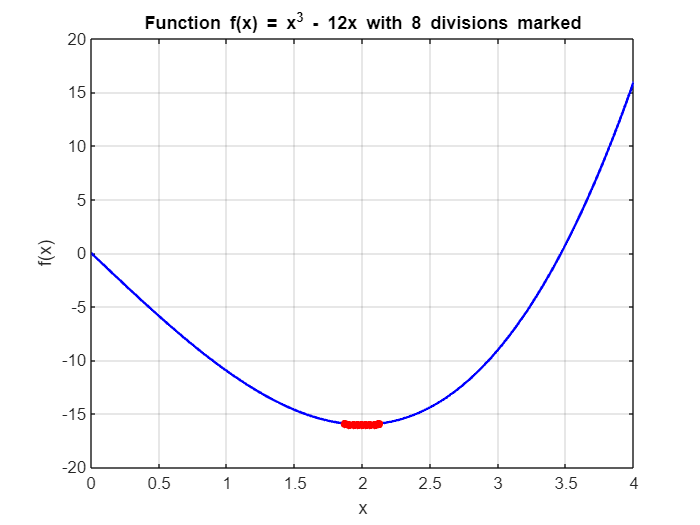

% Define the range and grid divisions
 a=1.875;
 b=2.125;
divisions=8;
step = (b-a)/divisions;

% Initialize variables for the minimum value and its location
min_val = Inf;
min_x = NaN;

% Grid search
for x = a:step:b
    current_val = f(x);
    if current_val < min_val
        min_val = current_val;
        min_x = x;
    end
end

% Plot the function
x_values = linspace(0, 4, 1000);
y_values = f(x_values);
figure;
plot(x_values, y_values, 'b-', 'LineWidth', 1.5); hold on;

% Mark the 8 divisions with red points
for x = a:step:b
    y_at_x = f(x);
    plot(x, y_at_x, 'r.','MarkerSize', 15);
end

xlabel('x');
ylabel('f(x)');
title('Function f(x) = x^3 - 12x with 8 divisions marked');
grid on;
hold off;

- Notice that the function has been divided into 8 subintervals. The function output is calculated at each one and the lowest one is determined. 

- In this case the function output at $x = 2$, i.e.  $f(2) = -16$, is the lowest obtained. Our new interval needs to bracket this value. Hence, we obtain the interval $[1.5 \quad 2.5]$. We know that this interval contains the local minimum.

- The size of this interval is 1 which is clearly greater than $0.001$, the acceptable error value, and therefore we need to continue.

- Change the intervals $a$ and $b$ in the code above.

- Now we see that the subinterval from the first iteration has been further subdivided. This leads to the new, even smaller, interval $[1.875\quad  2.125]$, which still gives a bound with an error greater than $0.001$.

Creating a code to calculate the interval

clearvars -except f
% Initial interval and grid divisions
a = 0;
b = 4;
divisions = 8;
step = (b-a)/divisions;

% Keep track of number of function evaluations
func_evals = 0;
iterations = 0;
% Iteratively refine the interval
while (b - a) > 0.001
    iterations = iterations + 1;

    min_val = Inf;
    min_x = NaN;
    
    % Evaluating function values over the subintervals
    for i = 0:divisions
        x = a + i * step;
        
        % Only evaluate function for new points
        if i > 0 && i < divisions
            func_evals = func_evals + 1;
            current_val = f(x);
            if current_val < min_val
                min_val = current_val;
                min_x = x;
            end
        end
    end
    
    % Refine the interval
    a = min_x - 1*step;
    b = min_x + 1*step;
    step = (b-a)/divisions;

    % Display the interval calculated at the current iteration
    fprintf('Iteration %d: Interval = [%f, %f]\n', iterations, a, b);
end

Iteration 1: Interval = [1.500000, 2.500000]
Iteration 2: Interval = [1.875000, 2.125000]
Iteration 3: Interval = [1.968750, 2.031250]
Iteration 4: Interval = [1.992188, 2.007812]
Iteration 5: Interval = [1.998047, 2.001953]
Iteration 6: Interval = [1.999512, 2.000488]



fprintf('The minimum lies in the interval [%f, %f]\n', a, b);

The minimum lies in the interval [1.999512, 2.000488]


fprintf('Total function evaluations: %d\n', func_evals);

Total function evaluations: 42


fprintf('Total iterations: %d\n', iterations);

Total iterations: 6


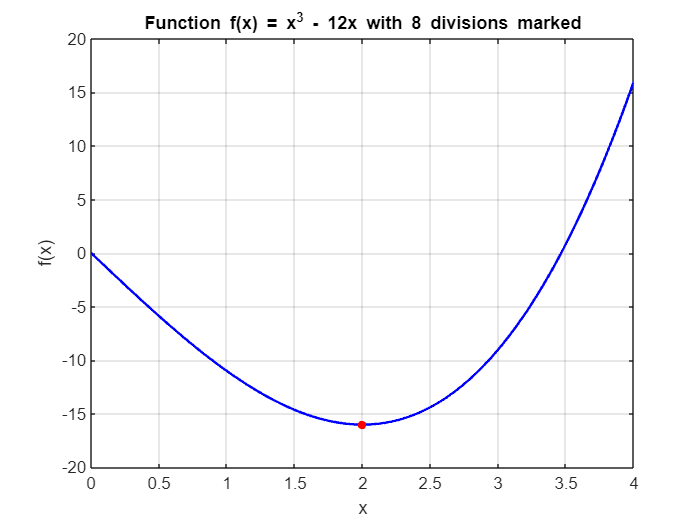


% Plot the function
x_values = linspace(0, 4, 1000);
y_values = f(x_values);
figure;
plot(x_values, y_values, 'b-', 'LineWidth', 1.5); hold on;

% Mark the 8 divisions with red points
for x = a:step:b
    y_at_x = f(x);
    plot(x, y_at_x, 'r.','MarkerSize', 15);
end

xlabel('x');
ylabel('f(x)');
title('Function f(x) = x^3 - 12x with 8 divisions marked');
grid on;
hold off;

- After 6 iterations we obtain the acceptable interval of $[1.9995\quad 2.0005]$. The actual minimum of 2 is clearly within this interval.

- alterar